Loading Image

img_path = input("Path for Image: ", 's')

img_path = 'ocean_original.jpg'

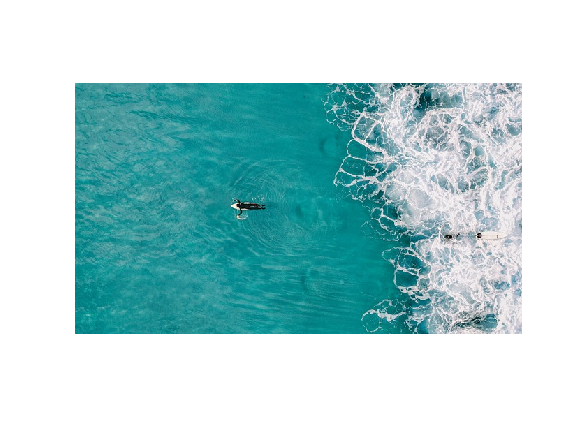

img = imread(img_path);
imshow(img);

disp("Size of Image: ");

Size of Image: 


s = size(img);
disp(s);

   359   640     3



r = s(1); c = s(2);
gray_img = rgb2gray(img);
L = watershed(gray_img);
disp("Watershed Transform based");

Watershed Transform based


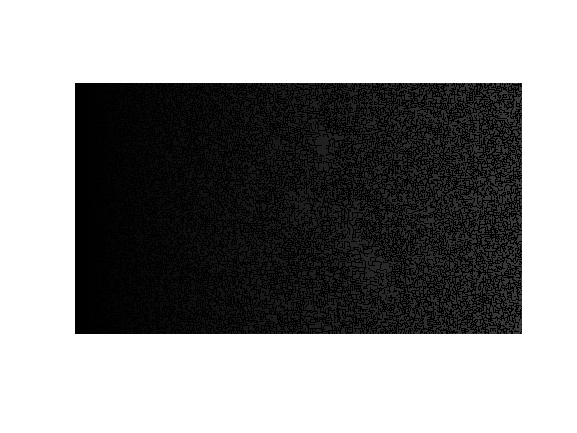

imshow(L);

Compute Energies, Find and Remove Seams

diff = abs(c-r)

diff = 281

for i = 1:diff
    gray_img = rgb2gray(img);
    L = watershed(gray_img);
   col_to_be_removed = shortest_path(L, r, c);
   new_img = zeros(r, c-1, 3, 'uint8');
   for x = 1:r
       col = col_to_be_removed(x);
       ny = 1;
       for y = 1:c
           if y ~= col
               new_img(x, ny, 1) = img(x, y, 1);
               new_img(x, ny, 2) = img(x, y, 2);
               new_img(x, ny, 3) = img(x, y, 3);
               ny = ny + 1;
           end
       end
   end
   img = new_img;
   c = c-1;
end
disp("Seam carved image");

Seam carved image


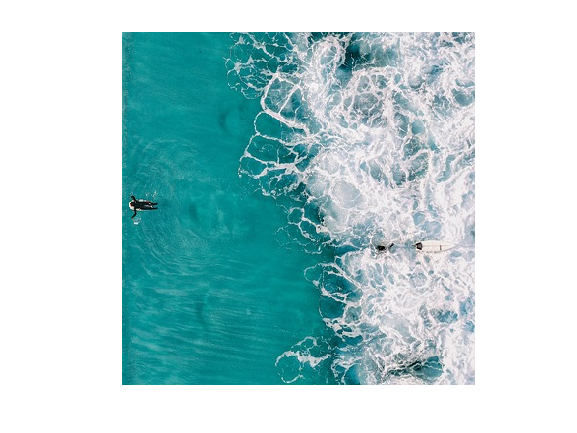

imshow(img);

gray_img = rgb2gray(img);
L = watershed(gray_img);
disp("Watershed Transform based after removing seams");

Watershed Transform based after removing seams


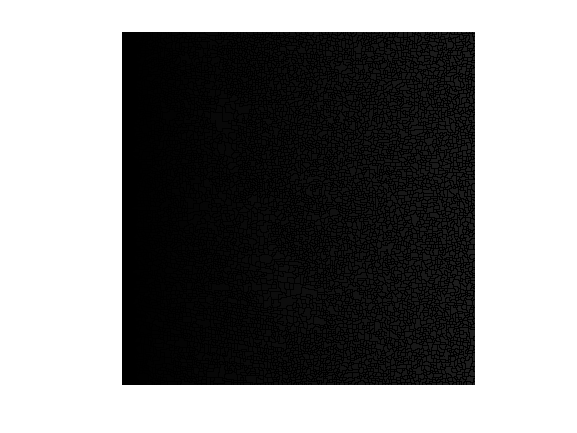

imshow(L);